# **Fourier Transform**

## Data Properties

Fs = 1000; % sampling frequency 1 kHz
t = 0:1/Fs:3-1/Fs; % sampling for 3 seconds
L = length(t); % Number of data points

## Components of Overall Signal

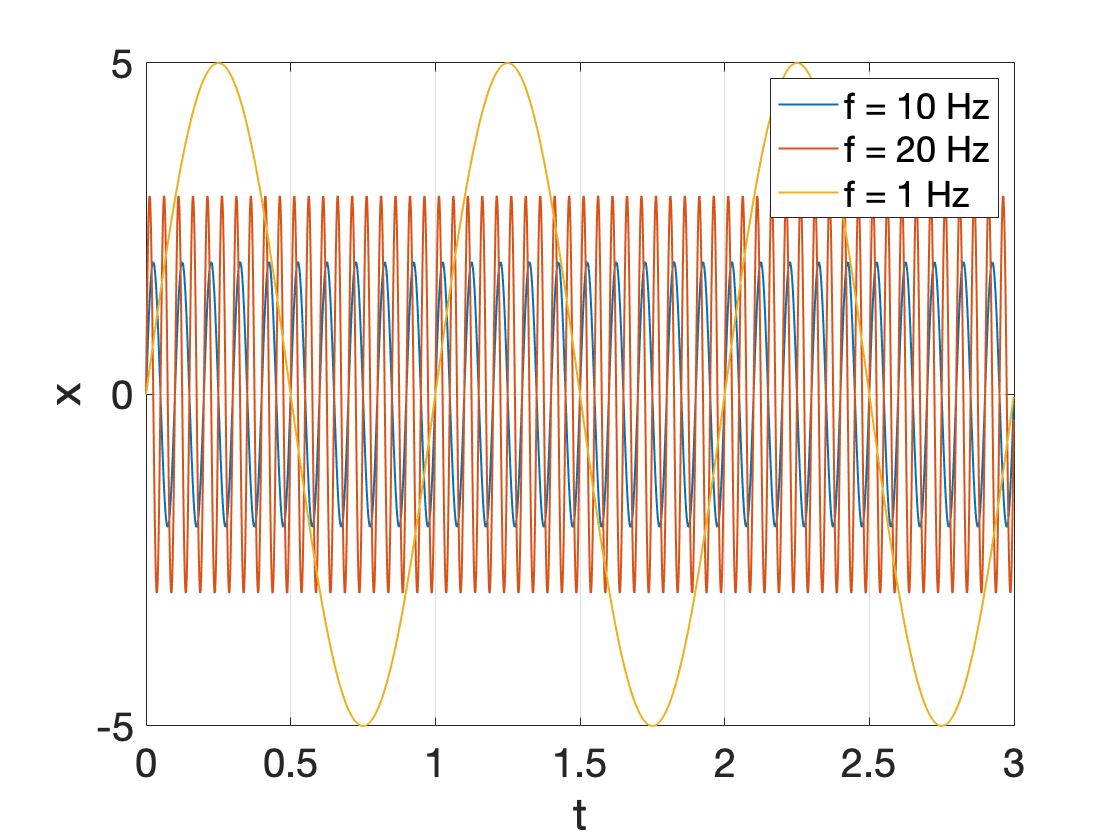

% Figure 
figure, hold on
set(gca,'FontSize',20,'FontName','Helvetica')
plot(t,2*sin(2*pi*10*t),'LineWidth',1);
plot(t,3*sin(2*pi*20*t),'LineWidth',1);
plot(t,5*sin(2*pi*1*t),'LineWidth',1);
xlabel('t'), ylabel('x')
legend('f = 10 Hz','f = 20 Hz', 'f = 1 Hz')
grid on, box on, hold off

## The Overall Signal

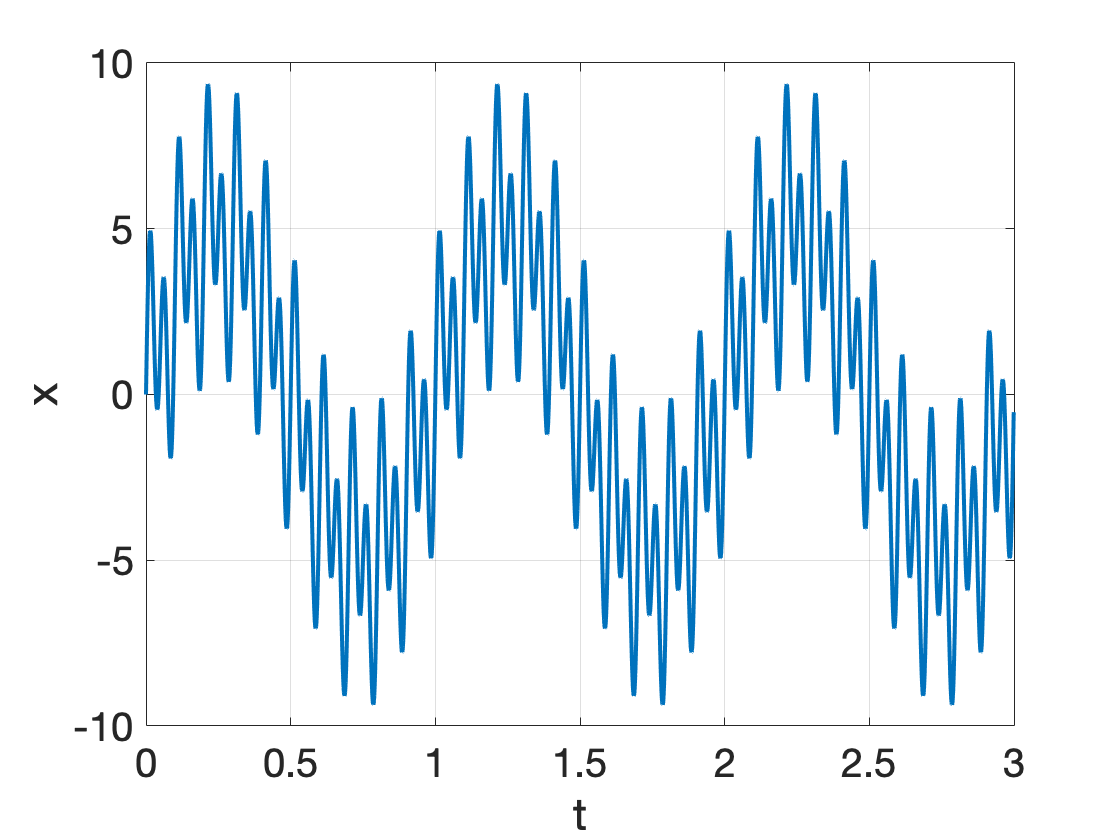

x = 2*sin(2*pi*10*t) + 3*sin(2*pi*20*t) + 5*sin(2*pi*1*t);
figure, hold on
set(gca,'FontSize',20,'FontName','Helvetica');
plot(t,x,'LineWidth',2);
xlabel('t'), ylabel('x')
grid on, box on, hold off

`From the overall signal, can we identify the building blocks?`

`Might be possible in this particular case, but it soon becomes impossible. `

## Fourier Transform to identify the basic components

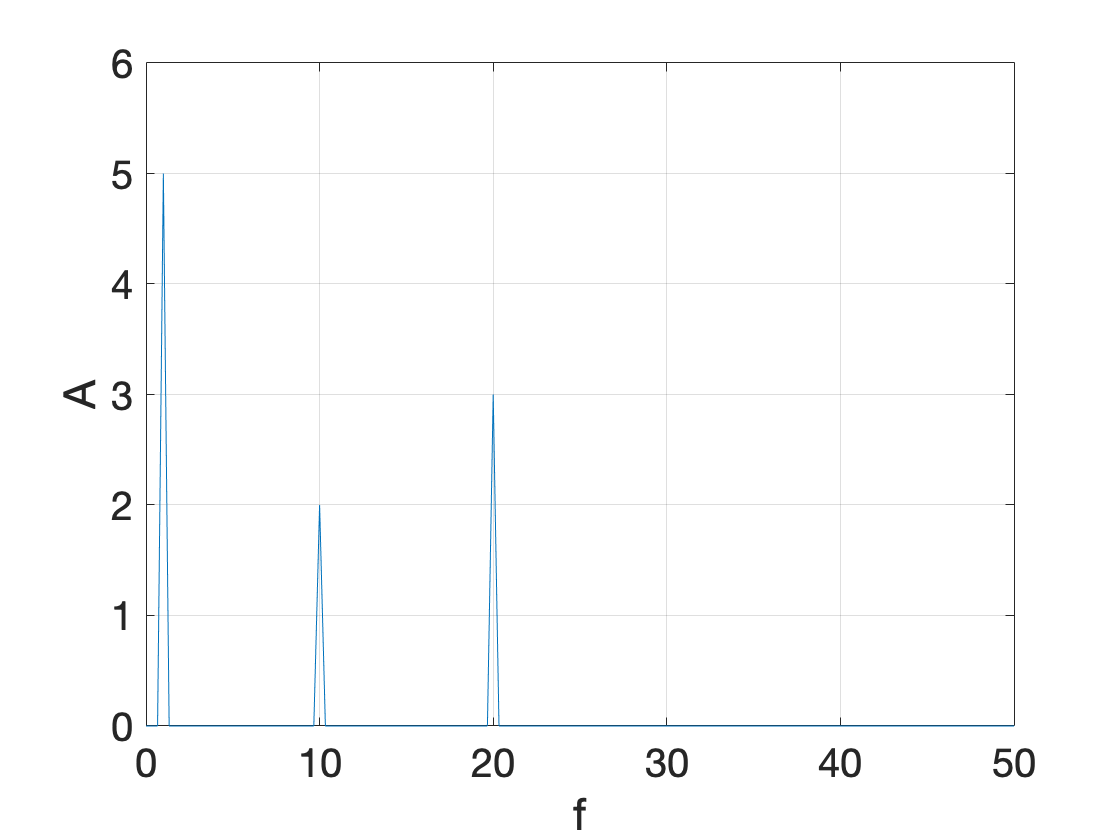

y = fft(x);
P2 = abs(y/L); % two sided spectrum
P1 = P2(1:L/2+1); % single sided amplitude spectrum
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
figure, hold on
set(gca,'FontSize',20,'FontName','Helvetica');
plot(f,P1);
xlim([0 50])
ylim([0 6])
xlabel('f'), ylabel('A')
grid on, box on, hold off